% given data
A = [-1, 0, 0, 0; 
    0, 2,  0, 0; 
    0, 0, 3, 4; 
    0, 0, -4, 3]
B = [0; 5; 0; 6]
C = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];
D = zeros(4, 1);
sys = ss(A, B, C, D);
x_0 = [1; 1; 1; 1];
eig_A = eig(A)

eig_A =    3.0000 + 4.0000i
   3.0000 - 4.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i



% Finding the matrix Κ by given spectrum of matrix (A+BK)
G1=[-1, 0, 0, 0; 
    0, -10, 0, 0; 
    0, 0, -3, 4; 
    0, 0, -4, -3]

G1 =     -1     0     0     0
     0   -10     0     0
     0     0    -3     4
     0     0    -4    -3


Y1 = [1, 1, 1, 1]

Y1 =      1     1     1     1



% Solving Sylvester's equations
cvx_begin sdp
variable P(4, 4)
A*P - P*G1 == B*Y1;
cvx_end;

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



% first string of matrix equals [0, 0, 0, 0] because determinant equls 0
% to determinant was more then zero let P(1, 1) = 1
% P is still root of Sylvester's equation 
P(1, 1) = 1

P =     1.0000         0         0         0
    1.6667    0.4167    0.1220    1.0976
   -0.7500   -0.1297    0.0800   -0.5600
    0.7500    0.4216    0.4400    0.9200



%finding controller
K = - Y1 * inv(P)

K =     1.8750   -5.7882   -8.2059    0.8235


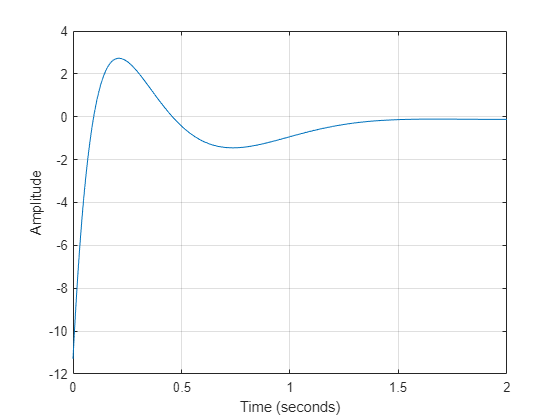

simtime = 2;
simul = sim("model1.slx", simtime);
plot(simul.u.Time, simul.u.Data);
grid on
xlabel('Time (seconds)');
ylabel('Amplitude');

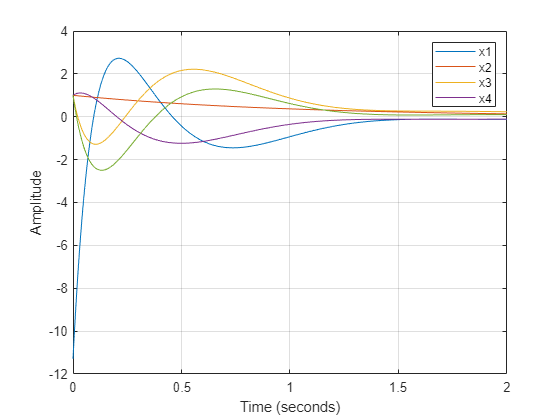

hold on;
plot(simul.x1.Time, simul.x1.Data);
plot(simul.x2.Time, simul.x2.Data);
plot(simul.x3.Time, simul.x3.Data);
plot(simul.x4.Time, simul.x4.Data);
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('x1', 'x2', 'x3', 'x4');